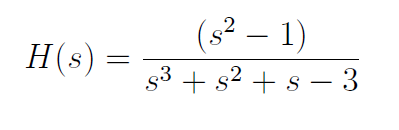

% syms t f H s
s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



H=((s^2-1))/(s^3+s^2+s-3)

H =
 
       s^2 - 1
  -----------------
  s^3 + s^2 + s - 3
 
Continuous-time transfer function.




zpk(H)  %zero pole gain model to see immediately the poles(zeros of denominator) and the zeros

ans =
 
      (s+1) (s-1)
  --------------------
  (s-1) (s^2 + 2s + 3)
 
Continuous-time zero/pole/gain model.




%  controlSystemDesigner(H)
pole(H)

ans =   -1.0000 + 1.4142i
  -1.0000 - 1.4142i
   1.0000 + 0.0000i


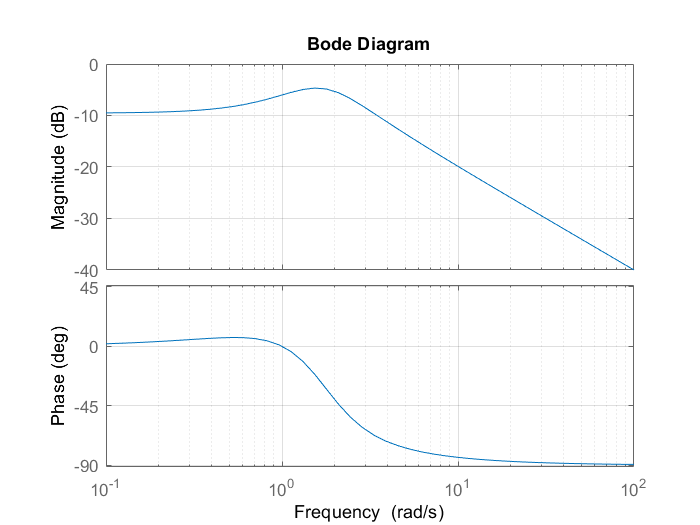

bode(H)
grid on

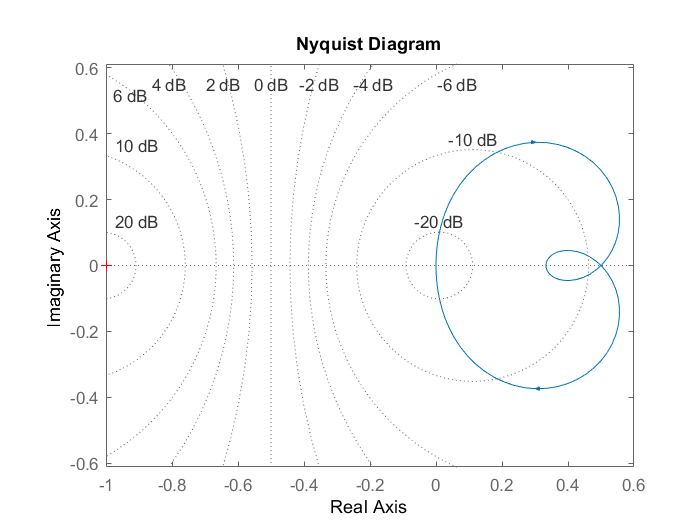

nyquist(H)
axis("equal")
grid on